Copyright 2020 The MathWorks, Inc.

# Rock-Paper-Scissors Demo in MATLAB with Analog Devices ToF Depth Camera

## Hardware Setup 

Follow these steps to setup the hardware:

- Connect ADI ToF camera to the Raspberry Pi 4 board.

- Connect Raspberry Pi 4 to the computer running MATLAB via ethernet. 

- On the Raspberry Pi, run "aditof-server.sh" before accessing the camera from MATLAB.

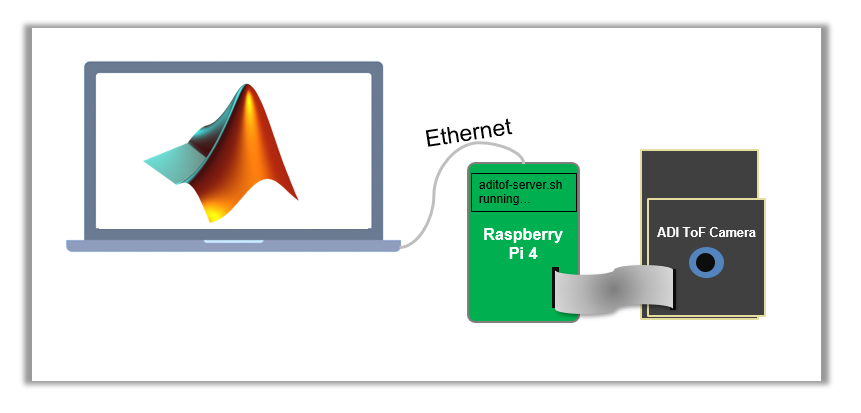

Close all figure windows and clear variable in the workspace.

close all; clear all;


### Setup the ADI ToF adapter in MATLAB

Check for adapter

imaqhwinfo

ans = struct with fields:
    InstalledAdaptors: {'aditofadapter'}
        MATLABVersion: '9.7 (R2019b)'
          ToolboxName: 'Image Acquisition Toolbox'
       ToolboxVersion: '6.1 (R2019b)'


NOTE: Run the section below only if the 'aditofadapter' adapter is not present in **InstalledAdaptors** field from above

You need to update the location of the DLL as appropriate for your setup.

imaqregister([pwd, '\aditofadapter.dll']);
imaqreset;

Open a connection to the ADI ToF camera. Be careful to not delete this. You cannot open a second connection to the camera. You must close this connection before you can open another one.  Be careful not to delete this variable.  Also make sure to update the IP address as appropriate for your setup.

depthVid = videoinput('aditofadapter', 1, '172.21.18.147');

Conn established
Connection Closed
Conn established


Now wait until `depthVid` shows up in the workspace before moving on to the next code section.

### Grab image from ToF camera

Note that hand must appear upright with fingers above the palm in order for the algorithm to work.

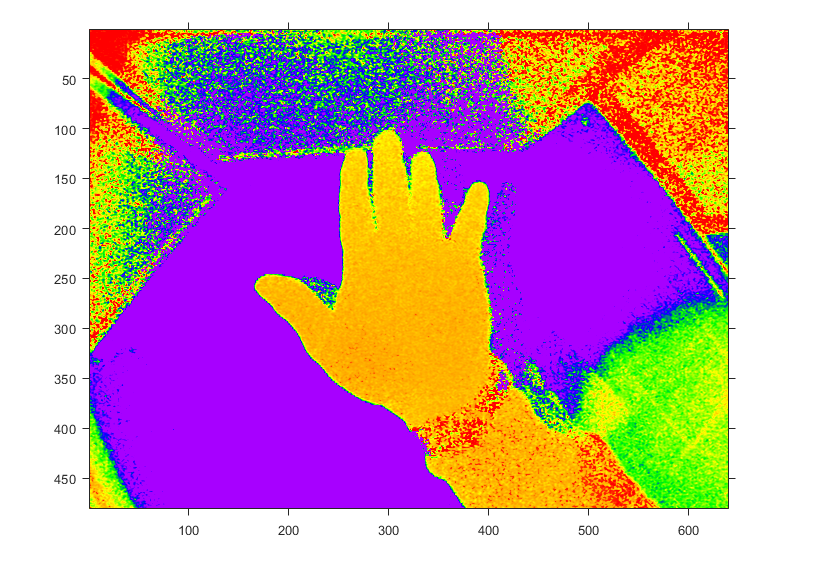

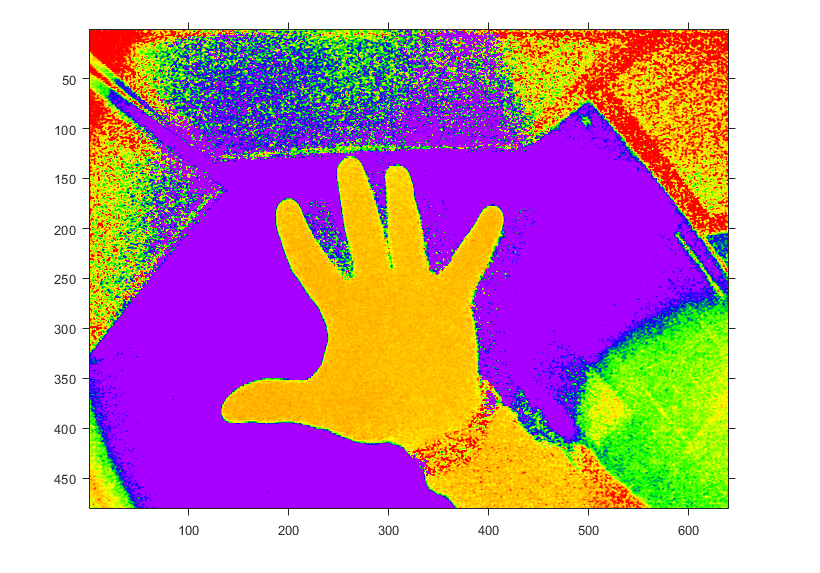

grabToFImages(depthVid);

### Filter the background noise

This might need to change depending on what's going on in the background of your setup.  This rectangle is setup to crop out thermal noise due to a halogen light that showed up at the top of the image. 

*NOTE: In this example, lets use a saved image file.*

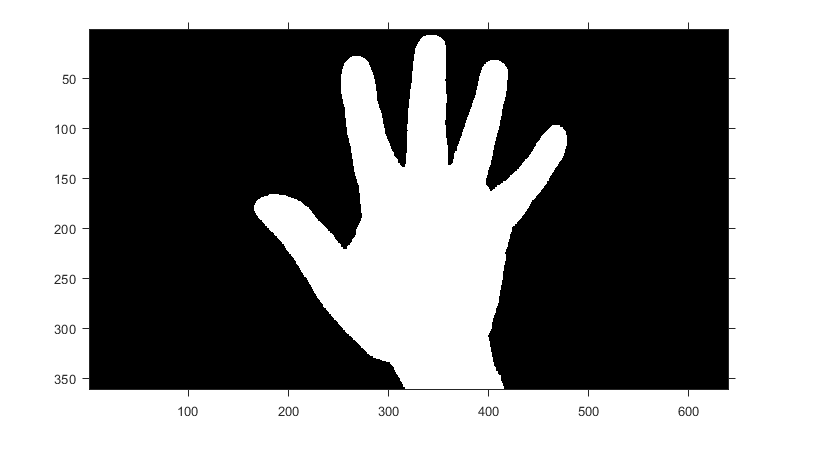

depthMap = imread('depthMap.png');

rect = [1 120 640 480];
I = imcrop(depthMap, rect);

% These are needed later to position text overlays
position1 = [(rect(3)-rect(1)-160) (rect(4)-rect(2)-49)];
position2 = [(rect(3)-rect(1)-160)  (rect(4)-rect(2)-19)];

%Use Color Thresholder App to determine the threshold value for your
%lighting and background conditions
colorThresholder(depthMap);

% Threshold to detect the hand
Ihsv = rgb2hsv(I);
BW = Ihsv(:,:,1) <= 0.25;
BW = imopen(BW,strel('disk',3));
BW = imfill(BW,'holes');
figure;f =imshow(BW);

### Find the hand in the image and measure its properties

Below is the code for classification of hand gesture - rock, paper or scissors

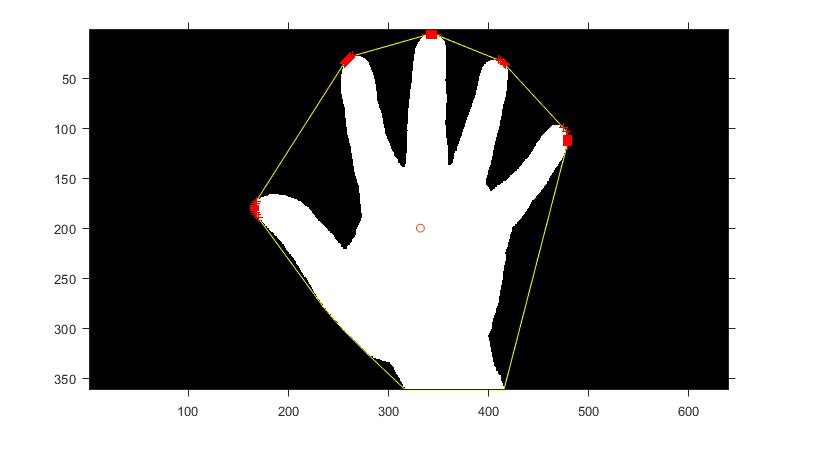

blobs = regionprops(BW,'Area','Centroid','ConvexHull');

% The hand is the largest blob in the image, some noise blobs may occur
[~,ind] = max([blobs.Area]);
blobs = blobs(ind);
c = blobs.Centroid;

% Use the convex hull to find fingers
x = blobs.ConvexHull(1:end-1,1); % Ignore last point which is same as first
y = blobs.ConvexHull(1:end-1,2);

imshow(BW); hold on; 
plot(x,y,'Color',[1 1 0]);
plot(c(1),c(2),'o');

% Sub-select for points on top half of the hand
x(y>c(2))= 0;
y(y>c(2))= 0;
x = nonzeros(x);
y = nonzeros(y);
hold on; plot(x,y,'+','Color',[1 0 0]);

### Determine if any fingers are extended

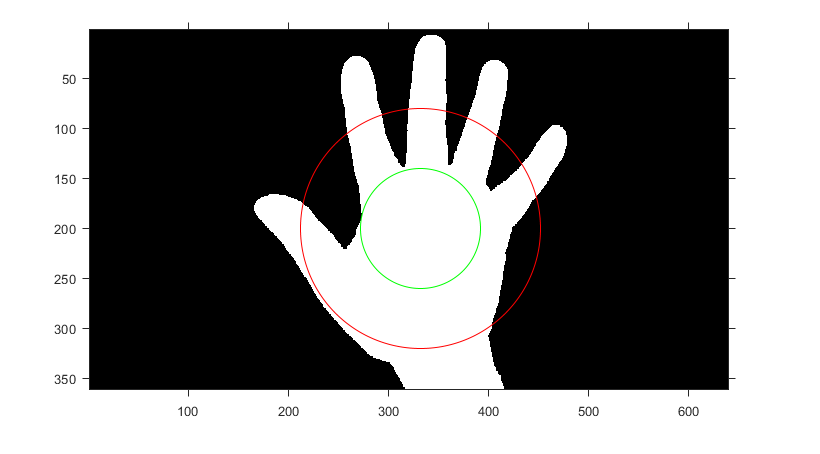

% Use distance transform as rough estimate radius of the hand's palm
bwd = bwdist(~BW);

% Find radius of the circle to nearest background from centroid
radius = bwd(round(c(2)), round(c(1)));
BWmarked = insertShape(double(BW),'circle',[c(1),c(2) radius],'Color','green');
BWmarked = insertShape(BWmarked,'circle',[c(1),c(2) 2*radius],'Color','red');
figure; imshow(BWmarked); 

If the distance is greater than 2 times the radius of the circle, then fingers are extended, so it must be **paper** or **scissors. **If not, it must be** rock. **

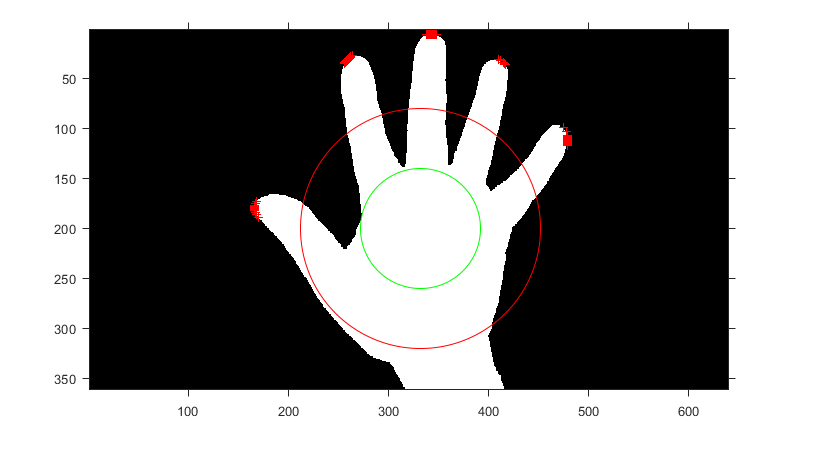

d = sqrt((x-c(1)).^2+(y-c(2)).^2);

% Sub-select for the points outside 2*radius estimate
x((d - 2*radius)<0) = 0;
y((d - 2*radius)<0) = 0;
x = nonzeros(x);
y = nonzeros(y);
figure;imshow(BWmarked);
hold on; plot(x,y,'+','Color',[1 0 0]);

%%
if length(x) < 1
    numfingers = 0;
    gesture = 'rock';
else
    gesture = 'open hand';
end

fprintf(['The gesture is ',gesture,'\n']);

The gesture is open hand


If it is open fist (**paper** or **scissors**), calculate number of finger tips detected

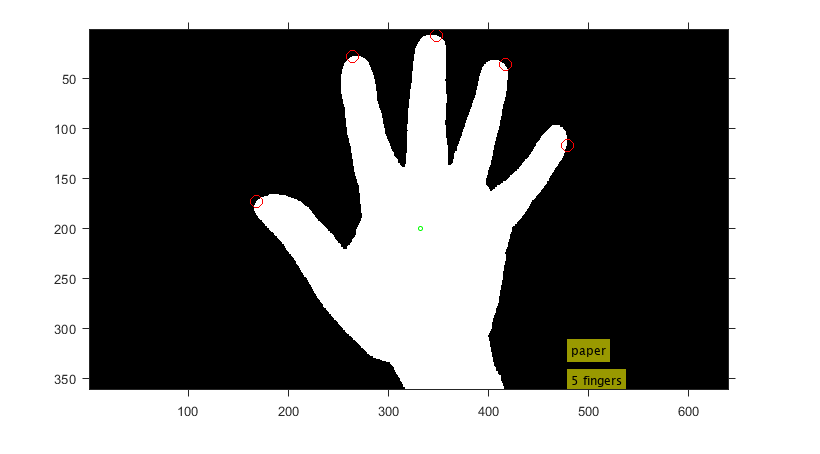

if length(x) > 0
    % suppress points that are within 10 pixels from each other
    dist_vec = zeros(1,length(x));
    p1 = [x(end) y(end)];
    p2 = [x(1) y(1)];
    dist_vec(1) = sqrt((p1(1)-p2(1)).^2+(p1(2)-p2(2)).^2);
     
    for i=2:length(x)
        p1 = [x(i-1) y(i-1)];
        p2 = [x(i) y(i)];
        dist_vec(i) = sqrt((p1(1)-p2(1)).^2+(p1(2)-p2(2)).^2);
    end
    
    fingersX = x(dist_vec(:) > 10); % select only points > 10 pixels from neighbors
    fingersY = y(dist_vec(:) > 10);
    
    numfingers = length(fingersX);
      
    if numfingers > 1
        if numfingers == 2
            gesture = 'scissors';
        elseif numfingers <= 5
            gesture = 'paper';
        end
    else
        gesture = 'Unclassified';
    end
    
    BWmarked = insertShape(double(BW),'circle',[c(1),c(2) 2],'Color','green');
    BWmarked = insertMarker(BWmarked, [fingersX fingersY], 'o', 'color', 'red', 'size', 6);
    
end

BWmarked = insertText(BWmarked, position1, gesture);
BWmarked = insertText(BWmarked, position2, [num2str(numfingers) ' fingers']);

figure;imshow(BWmarked);

fprintf(['The gesture is ',gesture,'\n']);

The gesture is paper


### Delete the depthVid object.

This will close the server connection on the Raspberry Pi.

delete(depthVid);

Connection Closed
